# Comparison of Daubechies wavelets

Compare father (scaling) and mother wavelets, lowpass and high-pass filter coefficients of some Daubechies wavelets.

waveinfo ('db')                                            % Daubechies family ( include 45 wavelets )

 Information on Daubechies wavelets.
 
    Daubechies Wavelets
 
    General characteristics: Compactly supported 
    wavelets with extremal phase and highest 
    number of vanishing moments for a given 
    support width. Associated scaling filters are
    minimum-phase filters.
 
    Family                  Daubechies
    Short name              db
    Order N                 N a positive integer from 1 to 45.
    Examples                db1 or haar, db4, db15
 
    Orthogonal              yes
    Biorthogonal            yes
    Compact support         yes
    DWT                     possible
    CWT                     possible
 
    Support width           2N-1
    Filters length          2N
    Regularity              about 0.2 N for large N
    Symmetry                far from
    Number of vanishing 
    moments for psi         N
 
    Reference: I. Daubechies, 
    Ten lectures on wavelets, 
    CBMS, SIAM, 61, 1994, 194-202.



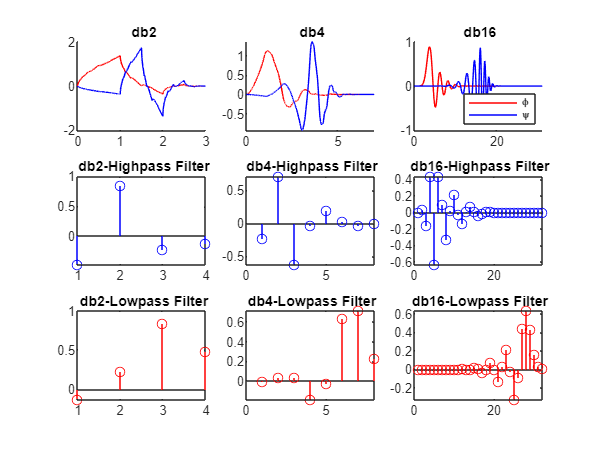

wname = [" db2", " db4", " db16"];                         % compare some Daubechies wavelets
Nw = length ( wname );
figure
for i = 1: Nw
    [phival, psival, tval] = wavefun (wname (i),10);       % compute phi and psi
    [Low , High] = wfilters (wname (i));                   % compute filters coefficients

    subplot (3,Nw ,i)
    hold on
    plot (tval , phival , "r")                             % plot scaling phi
    plot (tval , psival , "b")                             % plot mother psi
    title ( wname (i))
    if i == Nw
        legend("\phi","\psi", fontsize=6, Location="SouthEast") 
    end

    subplot (3,Nw ,Nw+i)
    stem (High ,"b")                                       % plot highpass filter
    title(wname{i}+"-Highpass Filter")
    subplot (3,Nw,2* Nw+i)
    stem (Low ,"r")                                        % plot lowpass filter
    title(wname{i}+"-Lowpass Filter")
end

Choose N:

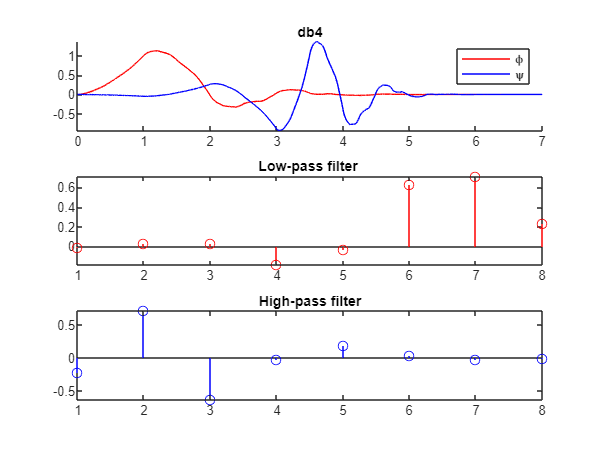

N = 4;
dbN = "db"+N;
[phival, psival, tval] = wavefun (dbN,10);
[Low , High] = wfilters(dbN);

figure
subplot(3,1,1)
hold on
plot (tval , phival , "r")                             % plot scaling phi
plot (tval , psival , "b")                             % plot mother psi
legend ("\phi" ,"\psi")
title(dbN)
subplot(3,1,2), stem (Low ,"r"), title("Low-pass filter ")
subplot(3,1,3), stem(High, "b"), title("High-pass filter")